# **Introduction to SSD**

This notebook is a guided tour of important functionalities in Software for Systems with Delays - SSD. Its content is mainly taken from the following conference paper

*S. Gumussoy, "****SSD - Software for Systems with Delays: Reproducable Examples and Benchmarks on Model Reduction and H2 Norm Computation****", accepted to IFAC Time Delay Workshop, Montreal, 2022.*

## **How to Define the Delay System**

### Delay Equations

SSD constructs the delay system in the form of

$\dot{x}(t) = \sum_{i=0}^{m_A} \ A_i\ x(t-h^A_i)+ \sum_{i=0}^{m_B} \ B_i\ x(t-h^B_i)$,

$y(t) = \sum_{i=0}^{m_C} \ C_i \ x(t-h^C_i)+ \sum_{i=0}^{m_D} \ D_i \ x(t-h^D_i)$.

### Function call

The delay system is constructed using **ssd** function as

*sys = ssd(A, hA, B, hB, C, hC, D, hD);*

### Argument structure

A, B, C, and D matrices are constructed as 3-dimensional matrices and hA, hB, hC, and hD are unique, increasing non-negative vectors as shown below.

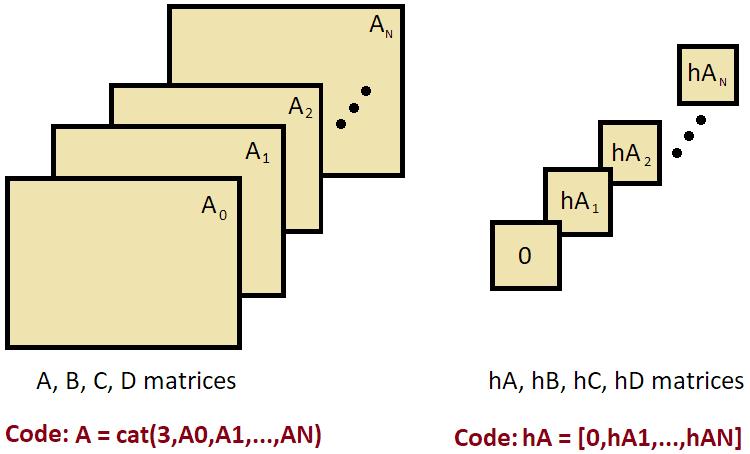

### An example

This example is taken from Elias Jarlebring et al., [Model reduction of time-delay systems using position balancing and delay Lyapunov equations](https://doi.org/10.1007/s00498-012-0096-9) paper, Example 5.1 in p.160.

$\dot{x}(t)=\left[ {\begin{array}{cc}
    -2 & -1 \\
    -3/2 & -1/2 \\
  \end{array} } \right]\ x(t) + 
\left[ {\begin{array}{cc}
    0 & 1/2 \\
    1 & 0 \\
  \end{array} } \right]\ x(t-1) + 
\left[ {\begin{array}{c}
    1 \\
    -1 \\
  \end{array} } \right]\ u(t)$,

$y(t) = \left[ {\begin{array}{cc}
    2 & 0.2 \\
  \end{array} } \right]\ x(t)$.

Define A, B and C matrices

A0 = [-2 -1; -3/2 -1/2];
A1 = [0 1/2; 1 0];
A = cat(3,A0,A1);
B = [1; -1];
C = [2  0.2];

Construct the delay system as

sys = ssd(A,[0 1],B,0,C,0)

sys =   ssd with properties:

       A: [2×2×2 double]
      hA: [0 1]
       B: [2×1 double]
      hB: 0
       C: [2 0.2000]
      hC: 0
       D: 0
      hD: 0
    name: []


Note that there is no D matrix in the example. Therefore, D and its delay is defined as [ ]. Alternatively, you may enter also zero matrix with appropriate dimensions and zero delay.

Additional info on ssd can be accessed by

help ssd

  ssd   Constructs state-space object with delays in the form,
        x'(t) = sum A_i*x(t-hA_i) + sum B_i*u(t-hB_i)
        y (t) = sum C_i*x(t-hC_i) + sum D_i*u(t-hD_i)
 
        SYS = ssd(A, DelaysA, B, DelaysB, C, DelaysC, D, DelaysD)
 
        A : State matrices of state equation, cat(3,A0,A1,...)
        hA: Unique and increasing delays of A matrices, [0,hA_1,...]
        B : Input matrices of state equation, cat(3,B0,B1,...)
        hB: Unique and increasing delays of B matrices, [0,hB_1,...]
        C : State matrices of output equation, cat(3,C0,C1,...)
        hC: Unique and increasing delays of C matrices, [0,hC_1,...]
        D : State matrices of output equation, cat(3,D0,D1,...)
        hD: Unique and increasing delays of D matrices, [0,hD_1,...]
 
  Example:
  sys = ssd(cat(3,[-2 -1;-1.5 -.5],[0 .5;1 0]),[0 1],[1;-1],0,[2 .2],0,[],0)

    Documentation for ssd



## Time and Frequency Domain Analysis

It helps to visually inspect the frequency and time domain plots of the delay system. We can simply look at its step response as

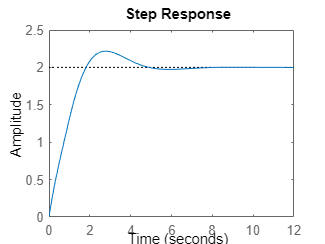

figure; step(sys)

or we can look at the responses of multiple systems

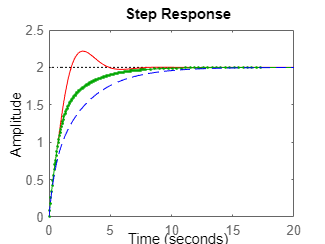

sys1 = ssd(A,[0 0.5],B,0,C,0);
sys2 = ssd(sum(A,3),0,B,0,C,0);
sys2.name='no delay';
figure; step(sys,'r',sys1,'g.-',sys2,'b--');

similarly, we can check its Bode magnitude plot,

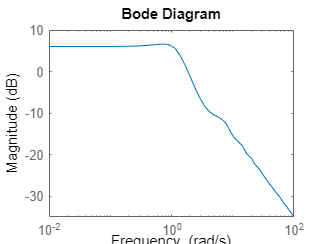

figure; bodemag(sys)

Currently, the other functions, **bode**, **sigma**, **nyquist** are available for visualization.

## Model Reduction

### The system gramians

We define the system gramians in the sense of position balancing [1]. They are reachability and observability measure for delay systems:

$W_c := \frac{1}{2\pi}\int_{-\infty}^{\infty}  \left(j\omega I-\mathcal{A}(j\omega) \right)^{-1}\mathcal{B}(j\omega) \mathcal{B}^*(j\omega) (-j\omega I-\mathcal{A}^*(j\omega))^{-1} d\omega$ and 

$W_o := \frac{1}{2\pi}\int_{-\infty}^{\infty}  \left(-j\omega I-\mathcal{A}^*(j\omega)\right)^{-1} \mathcal{C}^*(j\omega) \mathcal{C}(j\omega) \left(j\omega I-\mathcal{A}(j\omega)\right)^{-1} d\omega$.

where $\mathcal{A}(s)=\sum_{i=0}^{m_A} A_i\ e^{-h_i^A \ s}$, $\mathcal{B}(s)=\sum_{i=0}^{m_B} B_i\ e^{-h^B_i\ s}$ and $\mathcal{C}(s)=\sum_{i=0}^{m_C} C_i\ e^{-h^C_i\ s}$.

We can compute them easily by

[Wc,Wo] = gram(sys,'co')

For additional info,

help ssd.gram

Wc =     0.9274   -1.7427
   -1.7427    3.6294


Wo =     1.2673   -0.4130
   -0.4130    0.3674


### Balanced realization

Based on Wc and Wo, a transformation matrix is computed where the transformed states are ordered from easy to difficult according to the measure of how difficult to observe and reach them simultaneously. Such transformation matrix is the *balancing transformation* and the transformed system is the *balanced realization* [1, Algorithm 1]. We can transform the delay system into a balanced realization  and see the state contributions by plotting the `info` object.,

[sysb,info] = balreal(sys);

  gram  Computes the controllability and observability gramians
  of delay system.
 
         Wc = gram(SYS,'c') and Wo = gram(SYS,'o') computes
         controllability and observability gramians of delay
         system SYS (see SSD).
             
         [Wc,Wo] = gram(SYS,'co') computes both.
 
         Wc = gram(SYS,'c',OPT) and Wo = gram(SYS,'o',OPT)
         computes controllability and observability gramians
         with options (see SSDOPTIONS).
 
  Example: 
  sys = ssd(cat(3,[-2 -1;-1.5 -.5],[0 .5;1 0]),[0 1],[1;-1],0,[2 .2],0,[],0);
  [Wc,Wo] = gram(sys,'co')



figure; plot(info)

Its figure shows that the first transformed state's contribution is major.

Other details can be found by

help ssd.balreal

### Balanced reduction

By truncating the balancing transformation and applying onto the original delay system, the balanced reduction reduces the original system. We reduce the system and compare the step responses of the original and the reduced systems with

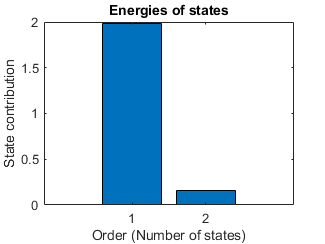

sysr = balred(sys,1);

figure; step(sys,sysr);

To acces its help, check

help ssd.balred

  balreal Transform delay system into the balanced realization.
 
         [SYSB,INFO] = balreal(SYS) computes the balanced
         realization SYSB of original delay system SYS (see
         SSD) and creates INFO for future computations
         capturing gramian information (see BALINFO).
 
         [SYSB,INFO] = balreal(SYS,OPT) computes with
         options (see SSDOPTIONS).
             
         SYSB = balreal(SYS,INFO) computes the balanced
         realization SYSB of original delay system SYS  without
         computing gramians and using the information in
         INFO (see BALINFO).
 
  Example: 
  sys = ssd(cat(3,[-2 -1;-1.5 -.5],[0 .5;1 0]),[0 1],[1;-1],0,[2 .2],0,[],0);
  sysb = balreal(sys)



### Frequency-limited Balanced Reduction

The system gramians are computed over the frequency intervals of interest [2]. The resulting reduced system approximates the dynamics better over the desired frequency range with less number of states.

Define Example 3 of order 9 in 3, p. 821-822 (This example is also available in [benchmarks_h2norm.mlx](matlab:open('./benchmarks_h2norm.mlx'))) as

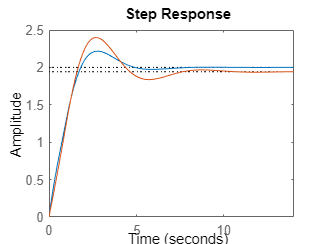

% define system matrices and delays of Example 3
n = 9; h=0.5;
x = ((0:(n-1))/(n-1))*pi;

A0 = ((n+1)/pi)^2*(diag(-2*ones(1,n)) + diag(ones(1,n-1),1) + diag(ones(1,n-1),-1)) + diag(20*ones(1,n));
A1 = diag(-4+x.*(1-exp(x-pi)));

  balred Reduces delay system in balanced gramian sense.
 
         [SYSR,INFO] = balred(SYS,NR) computes the reduced
         delay system RSYS with order NR of original delay
         system SYS (see SSD). INFO contains data to reduce
         system without recomputing gramians (see BALINFO).
         State contributions can seen by PLOT(INFO).
          
         [SYSR,INFO] = balred(SYS,NR,OPT) computes with options
         (see SSDOPTIONS).
 
         SYSRs = balred(SYS,NR,INFO) computes the reduced
         delay system without recomputing gramians.
 
  Example: 
  sys = ssd(cat(3,[-2 -1;-1.5 -.5],[0 .5;1 0]),[0 1],[1;-1],0,[2 .2],0,[],0);
  sysr = balred(sys,1)



A2 = diag(-.1*ones(1,n));
hA = [0 5*h 6*h];
B = [1;zeros(n-1,1)];
C = ones(1,n);

% define delay system in 
sys3 = ssd(cat(3,A0,A1,A2),hA,B,0,C,0,[],[]);

Compare the balanced reduction with frequency-limited balanced reduction over the frequency interval of interest, $[20, \infty)$

sys3r = balred(sys3,2);
opt = ssdoptions('FreqInt',[20 Inf]);
sys3rf = balred(sys3,2,opt);
opt_sigmaplot = sigmaoptions;
opt_sigmaplot.XLim = [20,100];
figure; sigma(sys3,sys3r,sys3rf,opt_sigmaplot);
legend('sys3','sys3r','sys3rf')

To see what other options can be configured,

help ssdoptions

### Balanced Reduction, more than one order

The object `info` stores the gramian related information and the full balancing transformation matrices. The function `balred` computes the reduced orders very fast when `info` is provided since it does not recompute gramian information. For example,

tic; [sys3r,info3] = balred(sys3,2); time_without_info=toc
tic; sys3r1 = balred(sys3,4,info3); time_with_info=toc

`Info` is a `balinfo` object and its details can be seen by

help balinfo

## $\mathcal{H}_2$ Norm Computation

Assuming the exponential stability of the delay system, its $\mathcal{H}_2$ norm is defined in frequency domain as,


$$\|G\|_2: = \sqrt{\frac{1}{2\pi} \int_{-\infty}^\infty trace\left(G^*(j\omega)G(j\omega)\right)dw}$$


where G is the transfer function of the delay system,

$G(s):=\left( \sum_{i=0}^{mC} C_ie^{-hC_i s}\right)
\left( sI- \sum_{i=0}^{mA} A_ie^{-hA_i s}\right)^{-1}
\left( \sum_{i=0}^{mB} B_ie^{-hB_i s}\right)$.

We borrow the hot shower problem from [3] (included in [benchmarks_h2norm.mlx](matlab:open('./benchmarks_h2norm.mlx')) as a first benchmark).

The system equations are


$$\dot{x}=-ax(t-h)+bu(t)$$


$y(t)=cx(t)$.

The closed form for the H2 norm is

$\|G\|_2^2=\frac{c^2b^2}{2a}\frac{cos(ah)}{1-sin(ah)}$.

We compare the analytical $\mathcal{H}_2$ norm results with our numerical ones for $h=0.1k$ where $k=1,\ldots,10$.

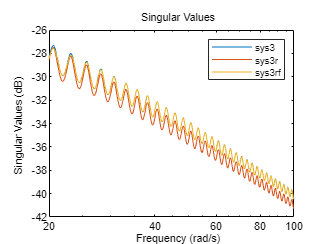

% define system parameters
a = 1; b = 1; c = 1;

% define delay range

h = 0.1:.1:1;


  ssdoptions   Constructs options for ssd object.
 
     AbsTol         Absolute error tolerance for integral. Default is 1e-3.
     RelTol         Relative error tolerance for integral. Default is 1e-3.
     Sparse         Enables sparse matrix computation. Default is false.
     FreqInt        Frequency intervals on which the gramian is defined.
                    Two-column matrix where each row defines an interval.
                    Default is [].
 
  Example:
  opt = ssdoptions('AbsTol',1e-2,'Sparse',true,'FreqInt',[2 4;5 8])

    Documentation for ssdoptions



% analytical values
h2 = (c^2*b^2/2/a)*(cos(a*h)./(1-sin(a*h)));


time_without_info = 0.0448

for ct=1:length(h)

time_with_info = 6.9410e-04

    % define delay system for each delay
    sys_hot_shower = ssd(cat(3,0,-a),[0 h(ct)],1,0,1,0,[],[]);

  balinfo  Constructs data for balanced realization and reduction.
 
     Rc    Cholesky matrix of controllability gramian.
     Ro    Cholesky matrix of observability gramian.
     sv    Hankel singular values.
     TL    Left matrix for balanced realization or reduction.
     TR    Right matrix for balanced realization or reduction.
 
  Example:
  sys = ssd(cat(3,[-2 -1;-1.5 -.5],[0 .5;1 0]),[0 1],[1;-1],0,[2 .2],0,[],0);
 
  [~,info1] = balreal(sys)  % using balreal
  [~,info2] = balred(sys,1) % using balred

    Documentation for balinfo



    % compute H2 norm
    happrox(ct) = h2norm(sys_hot_shower);
end

% compare analytical and numerical results
figure; plot(h,sqrt(h2),h,happrox,'o')
xlabel('h')
ylabel('H_2 norm')
title('H_2 norm wrt delay h')
legend('analytical','numerical')

For delay systems with large dimensions, enabling `sparse` option inside `ssdoptions` can speed up the computation considerably. Computing $\mathcal{H}_2$ norm without and with the sparse option enabled for the heated rod example of order 1000 [4] illustrates the difference. First, define the heated rod example.

% state matrix
n = 1000;
x = sin(((0:(n-1))/(n-1))*pi);
Delta0 = diag(x);
A0 = ((n-1)/pi)^2*(diag(-2*ones(1,n)) + diag(ones(1,n-1),1) + diag(ones(1,n-1),-1)) -2*Delta0;

% state delay matrix
A1 = 2*fliplr(Delta0);

% input and output matrices
B = ones(n,1)/norm(ones(1,n));
C = B';

% delay
tau = 1;

% define delay system
sys4 = ssd(cat(3,A0,A1),[0 tau],B,0,C,0,[],[]);

Then, by computing the $\mathcal{H}_2$  norm with and without sparse options, we see an order of magnitude difference.

tic; h2 = h2norm(sys4); time_without_sparse = toc
opt = ssdoptions('sparse',true);
tic; h2 = h2norm(sys4,opt); time_with_sparse = toc

To access for the help of `h2norm`, see

help ssd.h2norm

## What's next?

Check out [benchmarks_model_reduction.mlx](matlab:open('./benchmarks_model_reduction.mlx')) and [benchmarks_h2norm.mlx](http://benchmarks_h2norm.mlx) for additional benchmark problems and further use of SSD. For more technical details, please read the paper.

If you use SSD or any of the benchmarks, please cite the following paper:

*S. Gumussoy, "****SSD - Software for Systems with Delays: Reproducable Examples and Benchmarks on Model Reduction and H2 Norm Computation****", accepted to IFAC Time Delay Workshop, Montreal, 2022.*

Thanks for your interest!

## References

- E. Jarlebring et al. [Model reduction of time-delay systems using position balancing and delay Lyapunov equations](https://doi.org/10.1007/s00498-012-0096-9), 2013.

- W. Gawronski et al. [Model reduction in limited time and frequency intervals](https://doi.org/10.1080/00207729008910366), 1990.

- E. Jarlebring et al. [Characterizing and computing the H2 norm of time-delay systems by solving the delay Lyapunov equation](https://doi.org/10.1109/TAC.2010.2067510), 2011.

- J. Peeters and W. Michiels, [Computing the H2 norm of large-scale time-delay systems](https://doi.org/10.3182/20130204-3-FR-4031.00121), 2013.